# Dynamic_outlier_rejection

clear;
close all;
clc;
Time_window=[10,10,10];              %time_window for outlier rejection: fast/medium/slow
Threshold1=[0.5,0.5,0.5];            %Threshold for extremely outliers
vmax=[1.25,1,0.5];                   %velocity_upper_bound: fast/medium/slow
tt=[3,3,3];                          %paramerts for interpolation

## 1. Loading Data

path={'../../Planar Dataset/Dynamic/'};
UWBfile={'UWB_dynamic_exp_fast','UWB_dynamic_exp_mid','UWB_dynamic_exp_slow'};
OPTfile={'motion_capture_dynamic_exp_fast','motion_capture_dynamic_exp_mid','motion_capture_dynamic_exp_slow'};
velocity={'fast','mid','slow'};

for u=1:length(UWBfile)
    UWBfile_name=strcat(path+string(UWBfile(u)),'.csv');
    OPTfile_name=strcat(path+string(OPTfile(u)),'.csv');

    UWB=readtable(UWBfile_name);
    UWBdata=readmatrix(UWBfile_name);
    UWBdata(:,1)=datenum(UWB{:,1});
    OPT=readtable(OPTfile_name);
    OPTdata=readmatrix(OPTfile_name);
    OPTdata(1,:)=[];
    OPTdata(:,1)=datenum(OPT{:,1});

    quaternion_data=OPTdata(:,5:8);
    [yaw, pitch, roll]=quat2angle(quaternion_data,"ZYX");
    OPTdata=[OPTdata(:,[1,2,3]),yaw*180/pi];

## 2. Data Cleaning

#### Eliminate NaN

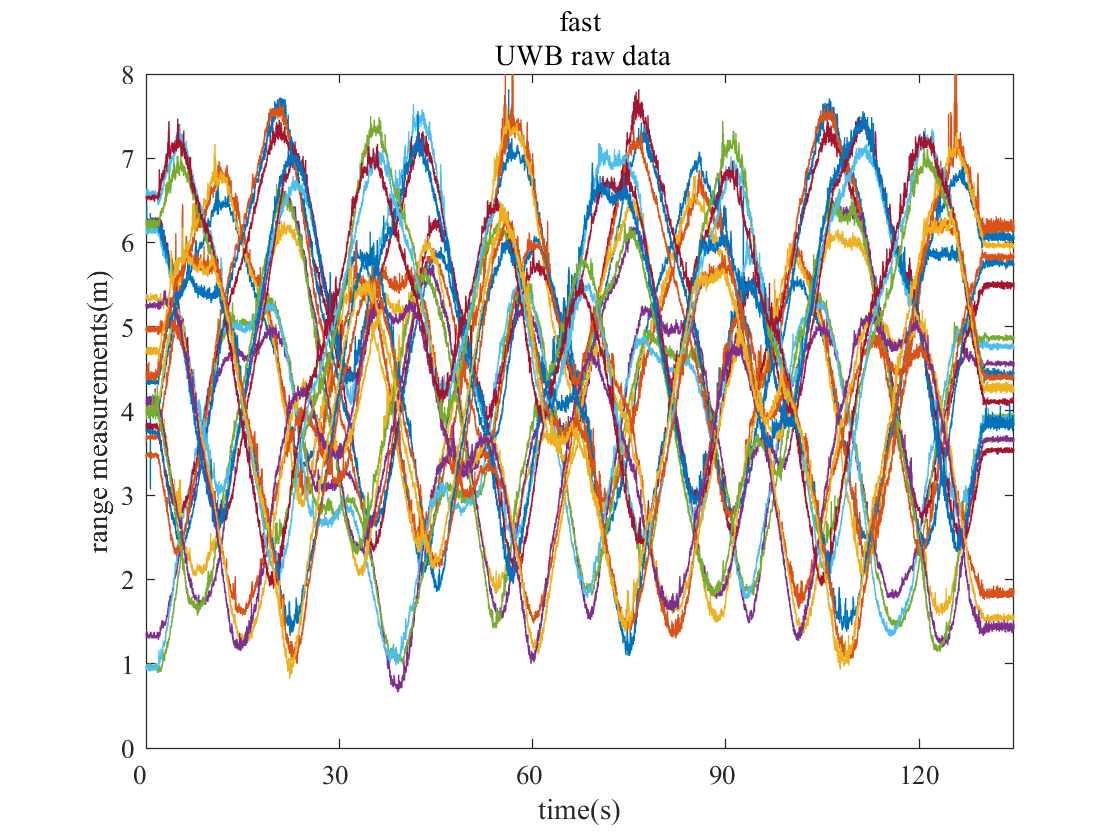

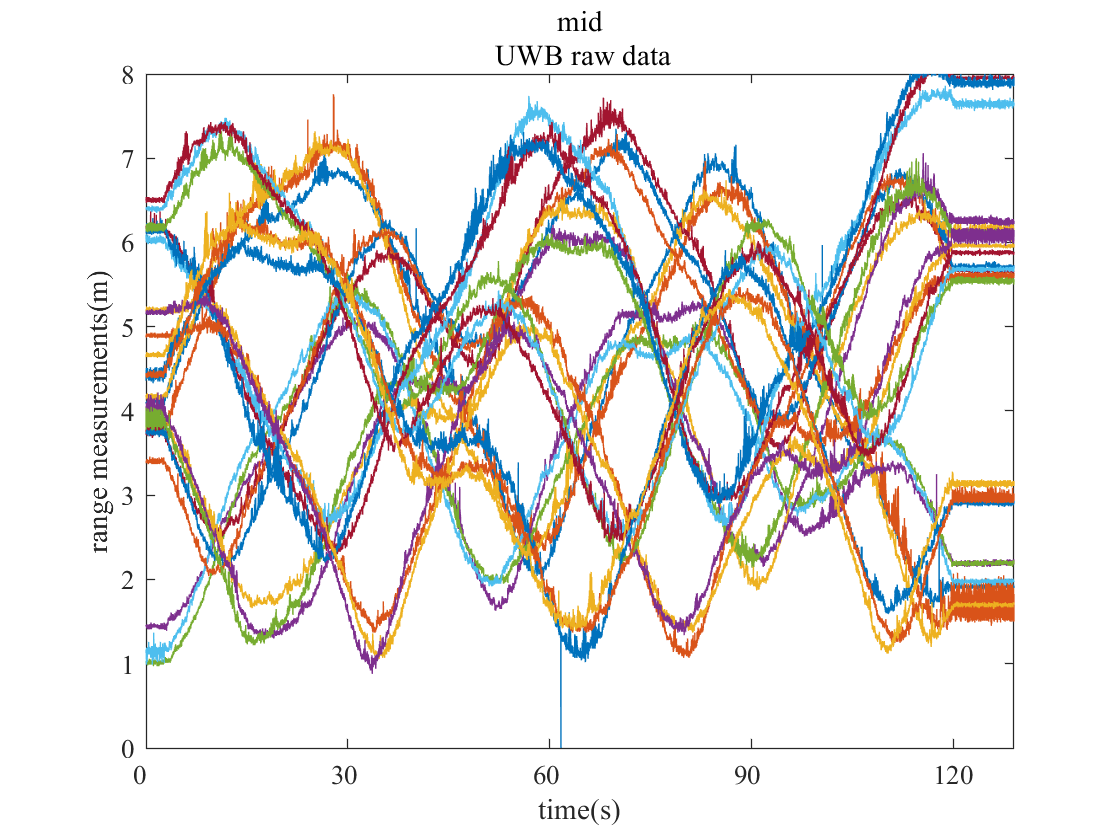

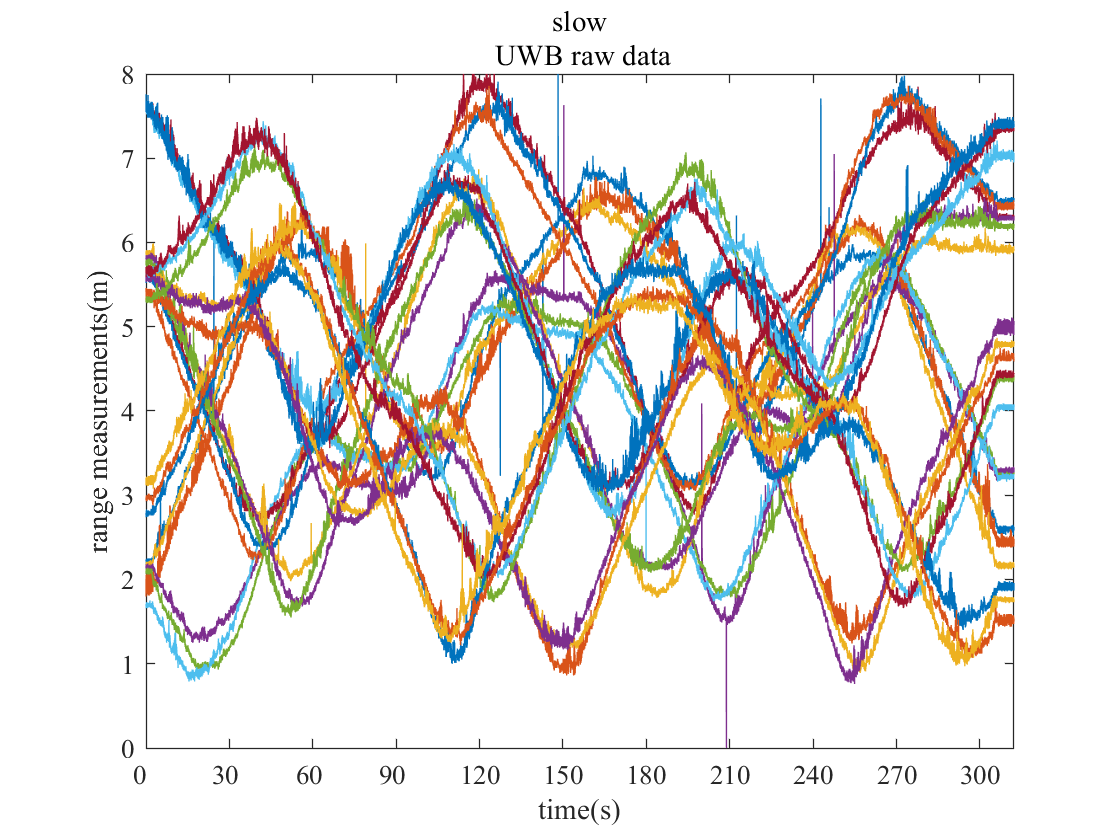

    [uwb_nan,~]=find(isnan(UWBdata));
    uwb_nan=unique(uwb_nan);
    UWBdata(uwb_nan,:)=[];

    figure
    plot(UWBdata(:,2:end))
    set(gca,'Fontname', 'Times New Roman')
    title([string(velocity(u)),' UWB raw data'])
    set(gca,'XTick',0:3000:length(UWBdata))
    set(gca,'XTicklabel',0:30:length(UWBdata)/100)
    set(gca,'YTick',0:1:8)
    xlim([0 length(UWBdata)])
    ylim([0 8])
    xlabel('time(s)')
    ylabel('range measurements(m)')
    saveas(gcf,strcat('Dynamic Image\'+string(velocity(u))+'_raw_data.png'));

#### Eliminate abnomal data and interpolate

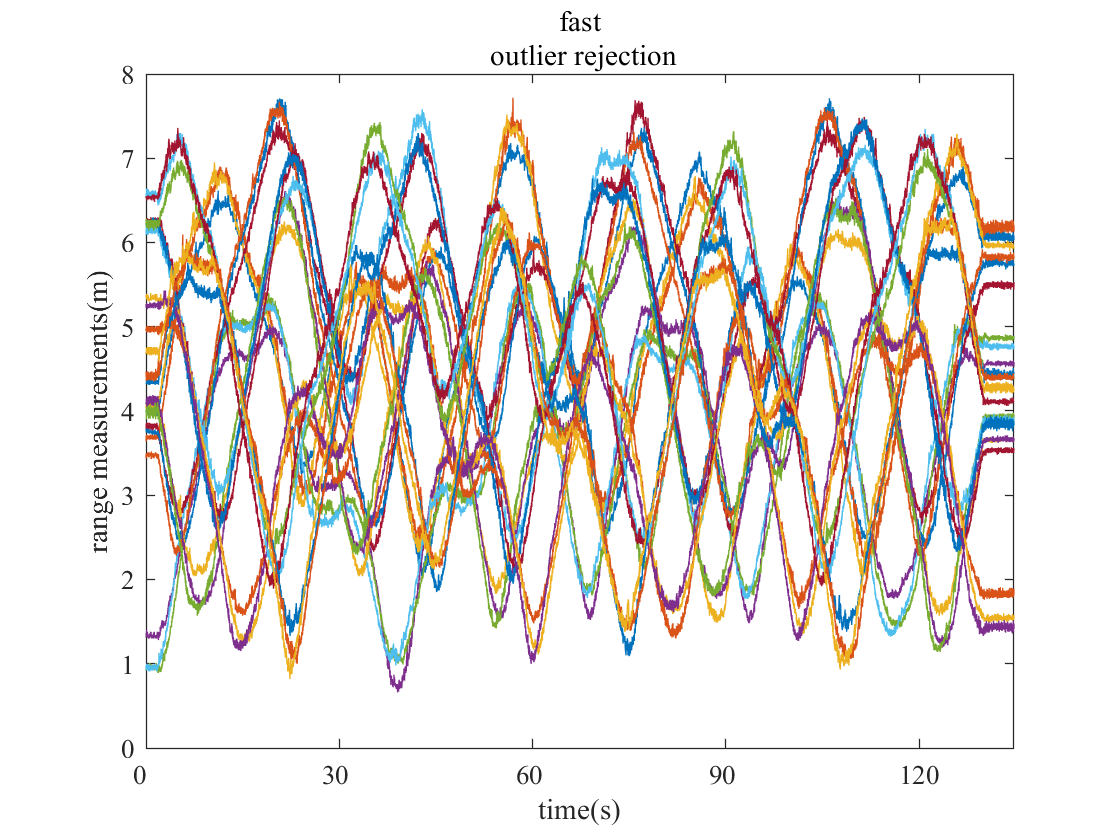

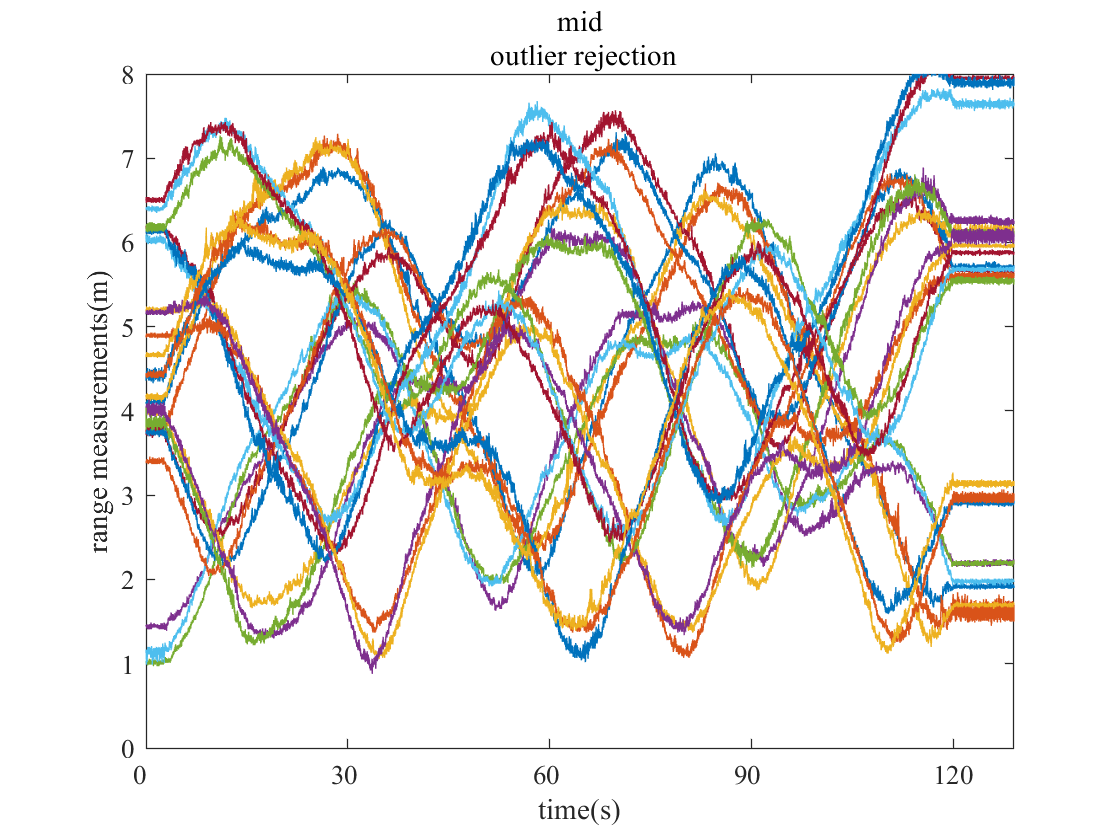

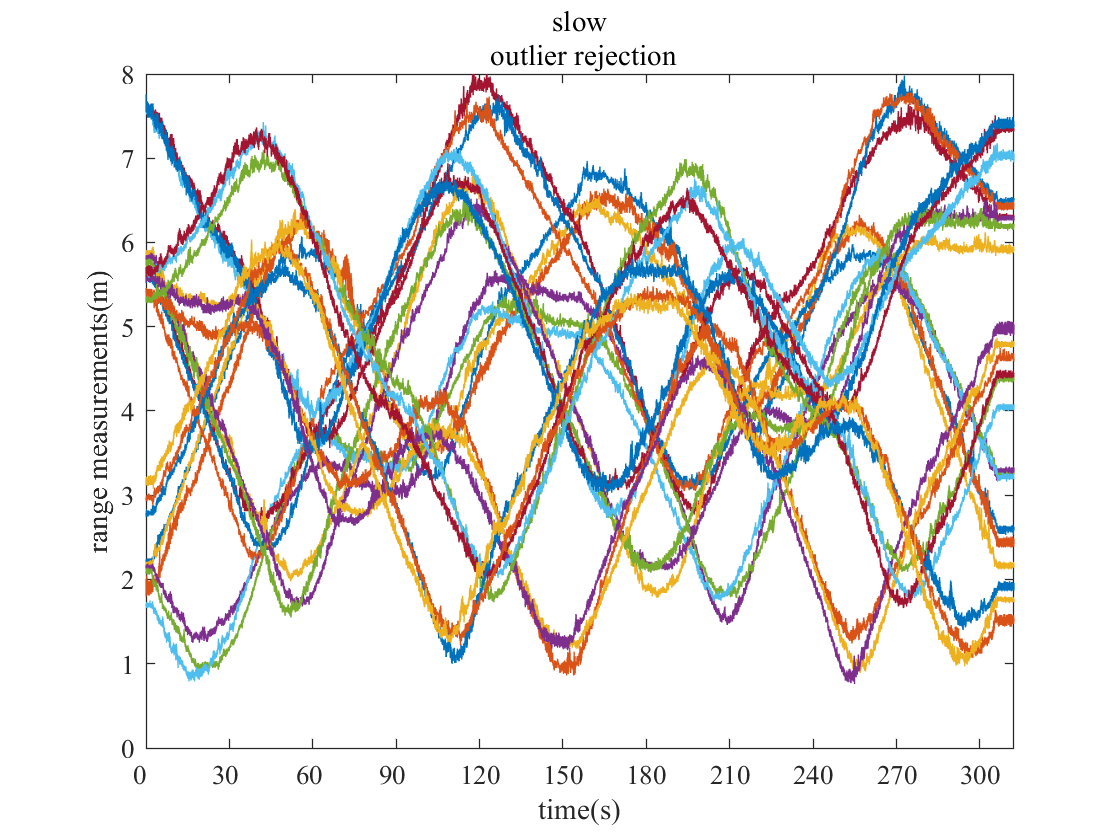

    %%Eliminate extremely abnormal measurements
    t=tt(u);%paramerts for interpolation
    abnormal_threshold1=Threshold1(u);
    v=vmax(u);
    for i=2:length(UWBdata)
        if max(UWBdata(i,:)-UWBdata(i-1,:))>abnormal_threshold1
            if i<t+1
                UWBdata(i,2:end)=mean(UWBdata(1:i-1,2:end));
            else
                UWBdata(i,2:end)=mean(UWBdata(i-t:i-1,2:end));
            end
        end
        if min(UWBdata(i,:)-UWBdata(i-1,:))<-abnormal_threshold1
            if i<t+1
                UWBdata(i,2:end)=mean(UWBdata(1:i-1,2:end));
            else
                UWBdata(i,2:end)=mean(UWBdata(i-t:i-1,2:end));
            end
        end
    end

    %%Outrlier Rejection
    time_window=Time_window(u);


    for i=t+1:length(UWBdata)
        index=[];
        if i<=time_window
            for j=1:i-1
                difference=UWBdata(i,2:end)-UWBdata(i-j,2:end)-v*j/100;
                idx=find(difference>0.1);
                index=[index,idx];    %the index of outlier measurement
            end            
        else
            for j=1:time_window
                difference=UWBdata(i,2:end)-UWBdata(i-j,2:end)-v*j/100;
                idx=find(difference>0.1);
                index=[index,idx];
            end
        end
        index=unique(index);
        for k=1:length(index)
            if i<t+1
                UWBdata(i,index(k)+1)=mean(UWBdata(1:i,index(k)+1));
            else
                UWBdata(i,index(k)+1)=mean(UWBdata(i-t:i,index(k)+1));
            end
        end
        
    end
    figure
    plot(UWBdata(:,2:end))
    set(gca,'Fontname', 'Times New Roman')
    set(gca,'XTick',0:3000:length(UWBdata));
    set(gca,'XTicklabel',0:30:length(UWBdata)/100)
    set(gca,'YTick',0:1:8)
    xlim([0 length(UWBdata)])
    ylim([0 8])
    xlabel('time(s)')
    ylabel('range measurements(m)')
    title([velocity(u),' outlier rejection'])
    saveas(gcf,strcat('Dynamic Image\'+string(velocity(u))+'_outlier_rejection.png'));

## 3. Save

    writematrix(UWBdata,'..\2_Alignment\UWB_dynamic_exp_outlier_rejection_'+strcat(string(velocity(u))+'.xlsx'));
    writematrix(OPTdata,'..\2_Alignmnet\motion_capture_dynamic_exp_outlier_rejection_'+strcat(string(velocity(u))+'.xlsx'));
end